**Find the area of the ...**

- **pure red (255,0,0) rectangle**

- **pure green (0,255,0) circle**

- **pure blue (0,0,255) triangle**

Read image

img = imread('shapes.png');


Show image

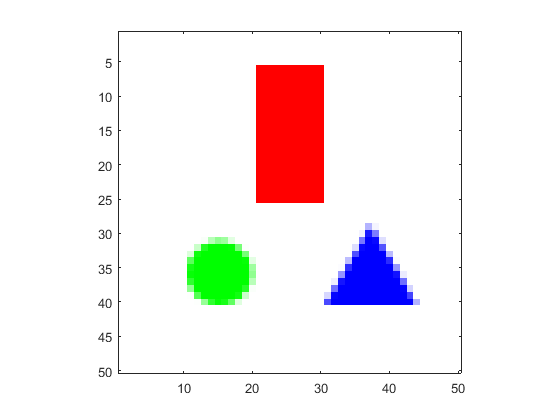

image(img)
axis tight; axis equal;

**Rectange**

Create a mask to indicate the pure red pixels in the image

mask2d = img(:,:,1)==255 & img(:,:,2)==0 & img(:,:,3)==0

mask2d = 50×50 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

Find the coordinates (rows,cols) of the located red pixels

[rows, cols] = find(mask2d);


Use max and min to determine the top-to-bottom and left-to-right bounds of the red pixels in the image and subtract to determine the height and width of the area covered by the black boardered rectangle

- Note as in the homework: Be sure to include� both� the first and last row or column when calculating dimensions. In other words, if the leftmost red pixel is in column 4 and the rightmost red pixel is in column 8, then the width of the bar is 5 pixels. 


height = max(rows)-min(rows)+1

height = 20

width = max(cols)-min(cols)+1

width = 10

Calculate area

areaOfRedRectangle = width * height

areaOfRedRectangle = 200

**Circle**

Create a mask to indicate the pure green pixels in the image

mask2d = img(:,:,1)==0 & img(:,:,2)==255 & img(:,:,3)==0

mask2d = 50×50 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

Find the coordinates (rows,cols) of the located green pixels

[rows, cols] = find(mask2d);


Use max and min to determine the top-to-bottom and left-to-right bounds of the green pixels in the image and subtract to determine the height and width of the area covered by the black boardered rectangle

- Note as in the homework: Be sure to include� both� the first and last row or column when calculating dimensions. In other words, if the leftmost red pixel is in column 4 and the rightmost red pixel is in column 8, then the width of the bar is 5 pixels. 


diameter = max(rows)-min(rows)+1

diameter = 8

radius = (diameter)/2

radius = 4

Calculate area

areaOfGreenCircle = pi*radius^2

areaOfGreenCircle = 50.2655

**Triangle**

Create a mask to indicate the pure blue pixels in the image

mask2d = img(:,:,1)==0 & img(:,:,2)==0 & img(:,:,3)==255

mask2d = 50×50 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

Find the coordinates (rows,cols) of the located blue pixels

[rows, cols] = find(mask2d);


Use max and min to determine the top-to-bottom and left-to-right bounds of the blue pixels in the image and subtract to determine the height and width of the area covered by the black boardered rectangle

- Note as in the homework: Be sure to include� both� the first and last row or column when calculating dimensions. In other words, if the leftmost red pixel is in column 4 and the rightmost red pixel is in column 8, then the width of the bar is 5 pixels. 


height = max(rows)-min(rows)+1

height = 10

base = max(cols)-min(cols)+1

base = 12

Calculate area

areaOfBlueTriangle = .5*base*height

areaOfBlueTriangle = 60